clear variables;
close all;
figure(1);hold on;
a=2;b=-5;c=1;
x2=-3:0.1:3;
y2=-2.5:0.1:4;
z2=-8:1:8;
[X2,Y2]=meshgrid(x2,y2);
Z2=-(a*X2+b*Y2)/c;
C(:,:,1)=zeros(size(Z2)); % red
C(:,:,2)=0.8*ones(size(Z2)); % green
C(:,:,3)=0.8*ones(size(Z2)); % blue
mesh(X2,Y2,Z2,C);

Plan 3D

    0.1235
    0.6178
   -0.3695
    1.2799
    0.8734
    1.8746
    0.1253
   -0.6994
   -1.5775
    0.4438



    1.1152
   -0.3062
   -1.6367
   -0.9341
   -1.3854
   -0.8760
   -0.2397
    0.1086
   -0.1703
    1.5015



   -0.7473
    5.2107
    0.9279
    5.4077
   -4.6301
    1.4657
   -3.9531
    1.4053
    1.7320
   -7.0481



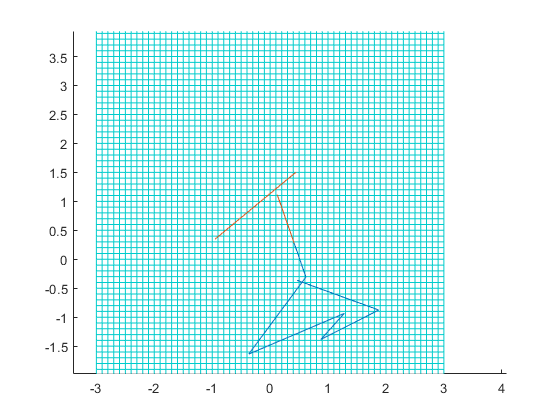

n = 10;
% x = linspace(-2,2,10);
% y = linspace(-2,2,10);
% z = linspace(-8,6,10);

i = -2;
j = 2;
x = (j-i).*rand(n,1) + i;
disp(x);

i = -2;
j = 2;
y = (j-i).*rand(n,1) + i;
disp(y);

i = -8;
j = 6;
z = (j-i).*rand(n,1) + i;
disp(z);

figure(1);
plot3(x,y,z);
axis equal;


U= rand(3,n); % matrice 2xn (concaténation de x et y)
U(1,:)=x;
U(2,:)=y;
U(3,:)=y;

% % vecteur directeur de la droite
N=[a,b,c];
N=N/norm(N);
% % matrice de projections sur la droite
P= N*N';

% % initialisation de la matrice 2xn contenant les abscisses (1ère ligne)
% % et les ordonnées (2ème ligne) des points projetés sur la droite
V=zeros(3,n);
% % calcul des coordonnées des points projetés (BOUCLE FOR OBLIGATOIRE)
     for k= 1:n 
        V(:,k)=P*U(:,k);
     end
% % affichage des points projetés (étoiles)
plot3(V(1,:),V(2,:),V(3,:)'*k');
% % on relie les points initiaux à leurs projections
    for k=1:n  
        plot3( [U(1,k), V(1,k)], [U(2,k), V(2,k)],[U(3,k), V(3,k)],'k');
    endclear variables;

close all;
figure(1);hold on;
a=2;b=-5;c=1;
x2=-3:0.1:3;
y2=-2.5:0.1:4;
z2=-8:1:8;
[X2,Y2]=meshgrid(x2,y2);
Z2=-(a*X2+b*Y2)/c;
C(:,:,1)=zeros(size(Z2)); % red
C(:,:,2)=0.8*ones(size(Z2)); % green
C(:,:,3)=0.8*ones(size(Z2)); % blue
mesh(X2,Y2,Z2,C);

Plan 3D

n = 10;
% x = linspace(-2,2,10);
% y = linspace(-2,2,10);
% z = linspace(-8,6,10);

i = -2;
j = 2;
x = (j-i).*rand(n,1) + i;
disp(x);

i = -2;
j = 2;
y = (j-i).*rand(n,1) + i;
disp(y);

i = -8;
j = 6;
z = (j-i).*rand(n,1) + i;
disp(z);

figure(1);
plot3(x,y,z);
axis equal;


U= rand(3,n); % matrice 2xn (concaténation de x et y)
U(1,:)=x;
U(2,:)=y;
U(3,:)=y;

% % vecteur directeur de la droite
N=[a,b,c];
N=N/norm(N);
% % matrice de projections sur la droite
P= N*N';

% % initialisation de la matrice 2xn contenant les abscisses (1ère ligne)
% % et les ordonnées (2ème ligne) des points projetés sur la droite
V=zeros(3,n);
% % calcul des coordonnées des points projetés (BOUCLE FOR OBLIGATOIRE)
     for k= 1:n 
        V(:,k)=P*U(:,k);
     end
% % affichage des points projetés (étoiles)
plot3(V(1,:),V(2,:),V(3,:)'*k');
% % on relie les points initiaux à leurs projections
    for k=1:n  
        plot3( [U(1,k), V(1,k)], [U(2,k), V(2,k)],[U(3,k), V(3,k)],'k');
    end


